# Cvičení 4 - B2M31AEDA

## Nahrání dat

Dejte si pozor na to, aby jste byli v MATLABu ve složce, kde máte umístěn soubor s daty (data.csv), nebo máte složku, ve které je soubor s daty, přidanou do cesty MATLABu (Matlab Path).

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week04' '\sem'])))
T = readtable('data.csv','ReadVariableNames',true);
nBins = 16;

untreated = repelem(struct( ...
    'data', NaN, ...
    'length', NaN, ...
    'mean', NaN, ...
    'std', NaN, ...
    'pdf', NaN, ...
    'normality', struct( ...
        'H', NaN, ...
        'pValue', NaN, ...
        'W', NaN) ...
), 3);
treated = repelem(struct( ...
    'data', NaN, ...
    'length', NaN, ...
    'mean', NaN, ...
    'std', NaN, ...
    'pdf', NaN, ...
    'normality', struct( ...
        'H', NaN, ...
        'pValue', NaN, ...
        'W', NaN) ...
), 3);

label = ["UPDRS_III_U" "stdPWR_U" "stdF0_U";
    "UPDRS_III_T" "stdPWR_T" "stdF0_T"];

parameter = ["UPDRS III score (-)", ...
    "Speech intensity standard deviation (dB)", ...
    "Fundamental frequency standard deviation (Hz)"];

## 1. Vizualizace dat

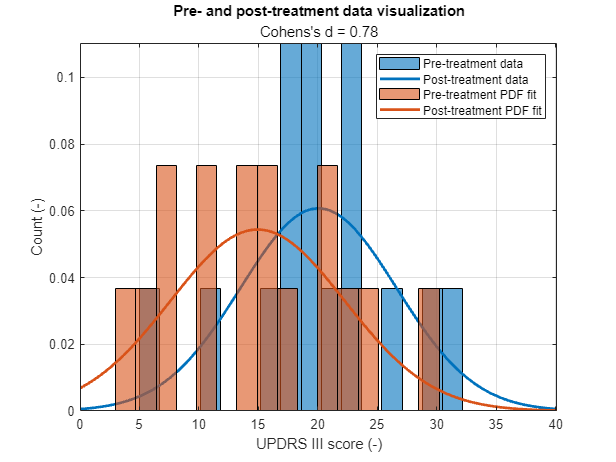

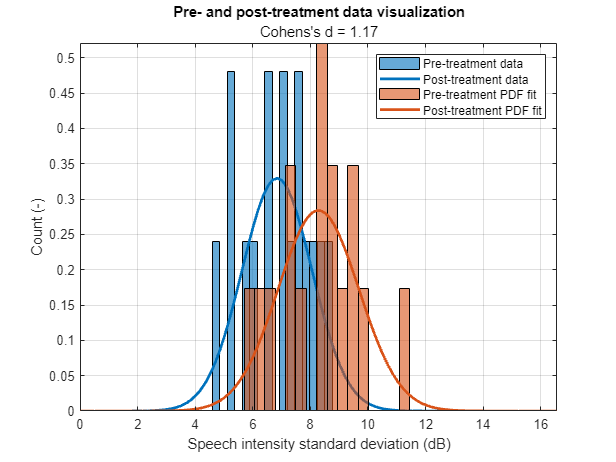

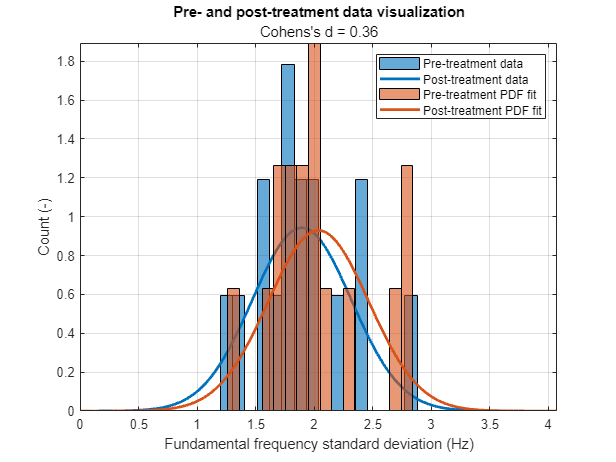

Cohens_d = nan(1,3);

for test = 1:3
    untreated(test).data = T.(label(1,test));
    untreated(test).length = length(untreated(test).data);
    untreated(test).mean = mean(untreated(test).data);
    untreated(test).std = std(untreated(test).data);

    treated(test).data = T.(label(2,test));
    treated(test).length = length(treated(test).data);
    treated(test).mean = mean(treated(test).data);
    treated(test).std = std(treated(test).data);

    xRange = linspace(0, max(2*untreated(test).mean, 2*treated(test).mean));
    untreated(test).pdf = normpdf(xRange, untreated(test).mean, untreated(test).std);
    treated(test).pdf = normpdf(xRange, treated(test).mean, treated(test).std);

    sigma_P = sqrt( ...
        ((untreated(test).length-1)*untreated(test).std^2 + ...
        (treated(test).length-1)*treated(test).std^2 ) / ...
        (untreated(test).length + treated(test).length + 2));
    Cohens_d(test) = abs(untreated(test).mean-treated(test).mean)/sigma_P;

    figure(test)
    hist1 = histogram(untreated(test).data, nBins, 'Normalization', 'pdf', 'FaceColor', '#0072BD');
    hold on
    plot(xRange, untreated(test).pdf, 'Color', hist1.FaceColor, 'LineWidth', 2)
    hist2 = histogram(treated(test).data, nBins, 'Normalization', 'pdf', 'FaceColor', '#D95319');
    plot(xRange, treated(test).pdf, 'Color', hist2.FaceColor, 'LineWidth', 2)
    hold off
    grid on
    axis tight
    xlabel(parameter(test))
    ylabel('Count (-)')
    legend('Pre-treatment data', ...
        'Post-treatment data', ...
        'Pre-treatment PDF fit', ...
        'Post-treatment PDF fit')
    title('Pre- and post-treatment data visualization')
    subtitle(sprintf('Cohens''s d = %.2f', Cohens_d(test)))
end

**Otázky:**

- *Vykazují zkoumané skupiny znaky normálního pravděpodobnostního rozdělení? Pokud ne, jaké pozorujete odchylky?*

Ano, skupiny vykazují znaky normálního rozdělení. Toto je vidět zejména po proložení dat křivkou odhadu normálního rozdělení, které dobře sedí na zaznamenaná data.

- *Je mezi skupinami treated-untreated **viditelný nějaký účinek léků? Je tento účinek pro pacienta zlepšením, nebo zhoršením stavu?*

Účinek medikace jsme posoudili na základě Cohenova d, které je nejběžnějším parametrem pro srovnávání odhadnutých distribucí dat a na základě něhož můžeme učinit závěr, že všechny tři provedené testy (skóre pacienta v dotazníku UPDRS III a směrodatné odchylky intenzity řeči pacienta a fundamentální frekvence pacientovy řeči) zaznamenávají alespoň slabý efekt medikace, přičemž na prvních dvou testech je lze efekt posoudit až jako silný.

## 1b. Ověření normality parametrů stdPWR, stdF0

- *Pouze jednou* zapište korektně hypotézy (H0, H1), které odpovídají vámi vybranému testu normality. Pokud použijete na všechny skupiny stejný test, budou (v principu) hypotézy stále stejné.

- Nastavte si hladinu statistické významnosti α.

- Proveďte testy, **korektně**  reportujte výsledky.

alpha = 0.01;
for test = 2:3
    [~, untreated(test).normality.pValue, untreated(test).normality.W] = swtest(untreated(test).data, alpha);
    [~, treated(test).normality.pValue, treated(test).normality.W] = swtest(treated(test).data, alpha);
end

### Hypotézy, reporty:

H0: Směrodatná odchylka intenzity, resp. fundamentální frekvence, řeči pacienta má normální rozdělení.

H1: Směrodatná odchylka intenzity, resp. fundamentální frekvence, řeči pacienta má rozdělení jiné nežli normální.

Hladina statistické významnosti: $\alpha =0\ldotp 01$.

Zvolený test: Shapirův-Wilkův pro jeho popularitu a významnost na menších vzorcích.

for test = 2:3
    assert(untreated(test).normality.pValue > alpha)
    fprintf(['Shapiro-Wilk test confirms that the dataset %s is normally distributed, ' ...
        'W(%d) = %.4f, p = %.4f.\n'], ...
        label(1, test), untreated(test).length-1, untreated(test).normality.W, untreated(test).normality.pValue)
    assert(treated(test).normality.pValue > alpha)
    fprintf(['Shapiro-Wilk test confirms that the dataset %s is normally distributed, ' ...
        'W(%d) = %.4f, p = %.4f.\n'], ...
        label(2, test), treated(test).length-1, treated(test).normality.W, treated(test).normality.pValue)
end

Shapiro-Wilk test confirms that the dataset stdPWR_U is normally distributed, W(15) = 0.9589, p = 0.6420.


Shapiro-Wilk test confirms that the dataset stdPWR_T is normally distributed, W(15) = 0.9808, p = 0.9696.


Shapiro-Wilk test confirms that the dataset stdF0_U is normally distributed, W(15) = 0.9545, p = 0.4805.


Shapiro-Wilk test confirms that the dataset stdF0_T is normally distributed, W(15) = 0.9095, p = 0.1144.


## 2. Manuální implementace párového t-testu


$$t=\ \frac{\mu_{\Delta \mathit{\mathbf{x}}} }{\sigma_{\Delta \mathit{\mathbf{x}}} /\sqrt{n}}\ ;\ \Delta \mathit{\mathbf{x}}={\mathit{\mathbf{x}}}_U -{\mathit{\mathbf{x}}}_T$$


delta = untreated(1).data - treated(1).data;
n = length(delta);
t = mean(delta)/std(delta)*sqrt(n);

### **Hypotézy, reporty:**

- **Navrhněte a slovy zapište hypotézy (H0, H1)**

- H0: V hodnotách skóre získaného pomocí dotazníku UPDRS III není po podání medikace statisticky významný rozdíl.

- H1: V hodnotách skóre získaného pomocí dotazníku UPDRS III je po podání medikace statisticky významný rozdíl.

- **Nastavte hodnotu α**

alpha = 0.05;

- **Proveďte párový t-test za pomocí vaší implementace**

p = tcdf([-t, t], n-1);
p = p(1) + (1-p(2));

- **Zjistěte příslušnou *****p*****-hodnotu **

fprintf('Manually implemented paired-samples t-test yields the value p = %.4f\n.', p);

Manually implemented paired-samples t-test yields the value p = 0.0269
.

- **Korektně reportujte výsledky + stručně interpretujte**

assert(p < alpha)
fprintf(['A paired-samples t-test was conducted to compare scores from the UPDRS III questionaire in pre-treatment\n' ...
    'and post-treatment conditions.\nThere was a significant difference in the results for pre-treatment (M = %.4f, ' ...
    'SD = %.4f) and\npost-treatment (M = %.2f, SD = %.2f) conditions; t(%d) = %.3f, p = %.3f.\nSpecifically, these ' ...
    'results suggest that the treatment improves the motor skills of patients\naffected by Parkinson''s disease.'], ...
    untreated(1).mean, untreated(1).std, treated(1).mean, treated(1).std, n-1, t, p);

A paired-samples t-test was conducted to compare scores from the UPDRS III questionaire in pre-treatment
and post-treatment conditions.
There was a significant difference in the results for pre-treatment (M = 20.0625, SD = 6.5673) and
post-treatment (M = 14.94, SD = 7.33) conditions; t(15) = 2.453, p = 0.027.
Specifically, these results suggest that the treatment improves the motor skills of patients
affected by Parkinson's disease.

## 3. Úloha

K následujícím otázkám navrhněte hypotézy, hodnoty α, proveďte analýzy pomocí vhodných statistických testů a stejně jako v předchozích částech výsledky správně reportujte a vyvoďte závěry.

- *Má podání léků vliv na řeč pacientů s PN z hlediska toho, jak moc dokáží měnit hlasitost svého projevu? Jaký je tento vliv (pozitivní/negativní,  silný/slabý, …)?*

- *Má podání léků vliv na monotónnost řeči pacientů s PN? Jaký je tento vliv (pozitivní/negativní,  silný/slabý, …)?*

- *Uvažujme ****pouze hodnoty naměřené před podáním léků.****Odráží automaticky naměřené hodnoty parametrů *stdPWR* a *stdF0* u jednotlivých pacientů jejich skóre z lékařem vyplněného dotazníku UPDRS? ***Pomocí vhodného zobrazení vykreslete ****vztah**** mezi všemi dvojicemi.**

### (a) Hypotézy, reporty:

- **Navrhněte a slovy zapište hypotézy (H0, H1)**

- H0: V hodnotách směrodatné odchylky intenzity řeči pacienta není po podání medikace statisticky významný rozdíl.

- H1: V hodnotách směrodatné odchylky intenzity řeči pacienta je po podání medikace statisticky významný rozdíl.

- **Nastavte hodnotu α**

alpha = 0.05;

- **Proveďte statistický test**

[~, p, ~, stats] = ttest(untreated(2).data, treated(2).data, 'Alpha', alpha);

- **Korektně reportujte výsledky + stručně interpretujte**

assert(p < 0.001)
fprintf(['A paired-samples t-test was conducted to compare standard deviations of patient''s voice intensity in\npre-treatment ' ...
    'and post-treatment conditions.\nThere was a significant difference in the results for pre-treatment (M = %.2f, SD = %.2f) ' ...
    'and\npost-treatment (M = %.2f, SD = %.2f) conditions; t(%d) = %.4f, p < 0.001.\nSpecifically, these results suggest that the ' ...
    'treatment improves the motor control over own vocal cords\nfor patients affected by Parkinson''s disease.'], ...
    untreated(2).mean, untreated(2).std, treated(2).mean, treated(2).std, stats.df, stats.tstat);

A paired-samples t-test was conducted to compare standard deviations of patient's voice intensity in
pre-treatment and post-treatment conditions.
There was a significant difference in the results for pre-treatment (M = 6.84, SD = 1.21) and
post-treatment (M = 8.28, SD = 1.40) conditions; t(15) = -6.1422, p < 0.001.
Specifically, these results suggest that the treatment improves the motor control over own vocal cords
for patients affected by Parkinson's disease.

### (b) Hypotézy, reporty:

- **Navrhněte a slovy zapište hypotézy (H0, H1)**

- H0: V hodnotách směrodatné odchylky fundamentální frekvence pacientovy řeči není po podání medikace statisticky významný rozdíl.

- H1: V hodnotách směrodatné odchylky fundamentální frekvence pacientovy řeči je po podání medikace statisticky významný rozdíl.

- **Nastavte hodnotu α**

alpha = 0.05;

- **Proveďte statistický test**

[~, p, ~, stats] = ttest(untreated(3).data, treated(3).data, 'Alpha', alpha);

- **Korektně reportujte výsledky + stručně interpretujte**

assert(p > alpha)
fprintf(['A paired-samples t-test was conducted to compare standard deviations of patient''s voice intensity\nin pre-treatment ' ...
    'and post-treatment conditions.\nThere was no significant difference in the results for pre-treatment (M = %.2f, SD = %.2f) ' ...
    'and\npost-treatment (M = %.2f, SD = %.2f) conditions; t(%d) = %.4f, p = %.3f.\nSpecifically, these results suggest that the ' ...
    'treatment does not significantly improve the motor\ncontrol over own vocal cords for patients affected by Parkinson''s disease.'], ...
    untreated(3).mean, untreated(3).std, treated(3).mean, treated(3).std, stats.df, stats.tstat, p);

A paired-samples t-test was conducted to compare standard deviations of patient's voice intensity
in pre-treatment and post-treatment conditions.
There was no significant difference in the results for pre-treatment (M = 1.90, SD = 0.42) and
post-treatment (M = 2.04, SD = 0.43) conditions; t(15) = -1.2460, p = 0.232.
Specifically, these results suggest that the treatment does not significantly improve the motor
control over own vocal cords for patients affected by Parkinson's disease.

### (c) Hypotézy, reporty:

- **Navrhněte a slovy zapište hypotézy (H0, H1)**

- H0: Hodnoty směrodatné odchylky intenzity řeči pacienta odráží jeho UPDRS III skóre.

- H1: Hodnoty směrodatné odchylky intenzity řeči pacienta neodráží jeho UPDRS III skóre.

- **Proveďte statistický test**

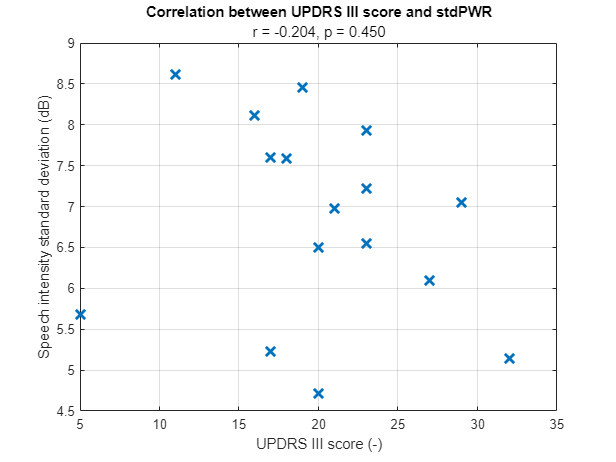

% Correlation between UPDRS score and patient's voice intensity standard deviation
[r, p] = corr(untreated(1).data, untreated(2).data, 'type', 'Pearson');

figure(4)
plot(untreated(1).data, untreated(2).data, 'x', 'MarkerSize', 10, 'LineWidth', 2)
xlabel(parameter(1));
ylabel(parameter(2));
grid on
title('Correlation between UPDRS III score and stdPWR')
subtitle(sprintf('r = %.3f, p = %.3f', r, p))

- **Korektně reportujte výsledky + stručně interpretujte**

- Na základě Pearsonova testu korelace můžeme usoudit, že mezi hodnotami směrodatné odchylky intenzity řeči pacienta a jeho UPDRS III skóre existuje pozue velmi slabá až slabá korelace (hodnota $|r|\approx 0\ldotp 2$ je hodnotou hraniční mezi velmi slabou a slabou korelací).

### (d) Hypotézy, reporty:

- **Navrhněte a slovy zapište hypotézy (H0, H1)**

- H0: Hodnoty směrodatné odchylky fundamentální frekvence pacientovy řeči odráží jeho UPDRS III skóre.

- H1: Hodnoty směrodatné odchylky fundamentální frekvence pacientovy řeči pacienta neodráží jeho UPDRS III skóre.

- **Proveďte statistický test**

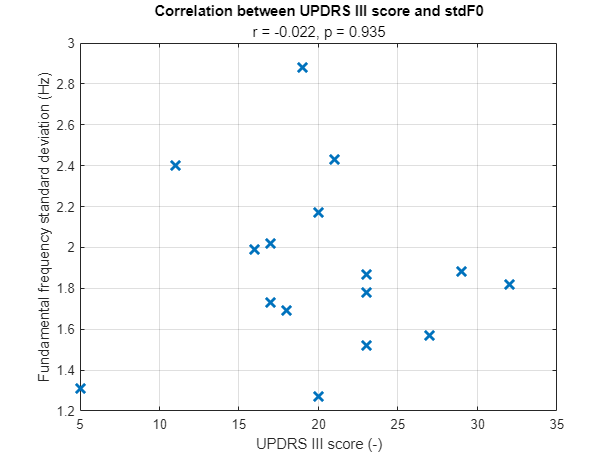

% Correlation between UPDRS score and patient's voice fundamental frequency standard deviation
[r, p] = corr(untreated(1).data, untreated(3).data, 'type', 'Pearson');

figure(5)
plot(untreated(1).data, untreated(3).data, 'x', 'MarkerSize', 10, 'LineWidth', 2)
xlabel(parameter(1));
ylabel(parameter(3));
grid on
title('Correlation between UPDRS III score and stdF0')
subtitle(sprintf('r = %.3f, p = %.3f', r, p))

- **Korektně reportujte výsledky + stručně interpretujte**

- Na základě Pearsonova testu korelace můžeme usoudit, že mezi hodnotami směrodatné odchylky fundamentální frekvence pacientovy řeči a jeho UPDRS III skóre existuje jen velmi slabá korelace.